# Region-of-Interest (ROI)

This example show how to analyze using ROI

for i = 1:10
    raw(i) = nirs.testing.simData([], @(t)nirs.testing.blockedStimDesign(t,15,25,2));
    % task-based 15s duration, 25s between onset, and 2 conditions
end

% Adding demographic manually
% Let's assume that the SubjectID is in the correct order
for i = 1:10
    raw(i).demographics('Subject') = ['S' num2str(i)];
end

%Let's make up the table contain SubjectID, Group, AgeMonths, ADHD
for i = 1:10; Subject{i,1} = ['S' num2str(i)]; end
for i = 1:5; Group{i,1} = ['S1']; end
for i = 6:10; Group{i,1} = ['S2']; end
AgeMonths = [60; 65; 68; 60; 69; 72; 61; 68; 70; 66];
ADHD = [2; 6; 3; 9; 5; 7; 3; 7; 5; 4];
demo = table(Subject, Group, AgeMonths, ADHD);

job=nirs.modules.AddDemographics;
job.allowMissing = true;
job.demoTable=demo;
job.varToMatch='Subject';
raw=job.run(raw);

nirs.createDemographicsTable(raw);

% Get hb data
job = nirs.modules.RenameStims();
job.listOfChanges = {'A',  'TaskA'; 'B', 'TaskB'};
job = nirs.modules.Resample(job);
job.Fs = 1; %For speed
job = nirs.modules.OpticalDensity(job);
job = nirs.modules.BeerLambertLaw(job);
hb = job.run(raw);

% First Level
job = nirs.modules.GLM();
Stats = job.run(hb);

Finished   10 of   10.


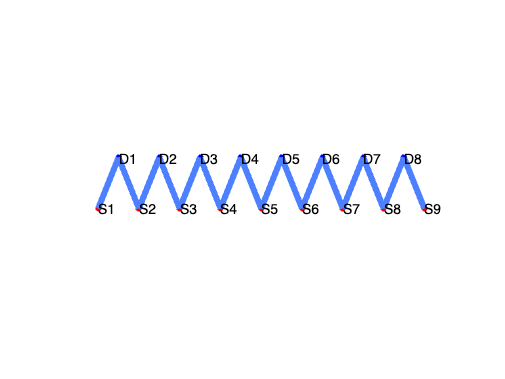


% Second-level or group-level
job = nirs.modules.MixedEffects();
job.formula = 'beta ~ -1  + cond + cond:ADHD + (1|Subject)';
job.robust = true; %Recommended to use the robust version
job.include_diagnostics = true; %to see scatter plot
GroupStats1 = job.run(Stats);

GroupStats1.probe.draw


% Let's devide this probe into 4 region
% Region1: Any probe connect to D1 and D2
% Region2: Any probe connect to D3 and D4
% Region3: Any probe connect to D5 and D6
% Region4: Any probe connect to D7 and D8

MeasList = [NaN 1; NaN 2];
Region{1} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [NaN 3; NaN 4];
Region{2} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [NaN 5; NaN 6];
Region{3} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});
MeasList = [NaN 7; NaN 8];
Region{4} = table(MeasList(:,1),MeasList(:,2),'VariableNames',{'source','detector'});

% This example to do the ROI in group level
[ROIGrouptable, ROIGroupstats] = nirs.util.roiAverage(GroupStats1,Region,{'Region1','Region2','Region3','Region4'});
ROIGroupstats.probe.link

ans = 8×2 table
        ROI         type  
    ___________    _______

    {'Region1'}    {'hbo'}
    {'Region1'}    {'hbr'}
    {'Region2'}    {'hbo'}
    {'Region2'}    {'hbr'}
    {'Region3'}    {'hbo'}
    {'Region3'}    {'hbr'}
    {'Region4'}    {'hbo'}
    {'Region4'}    {'hbr'}


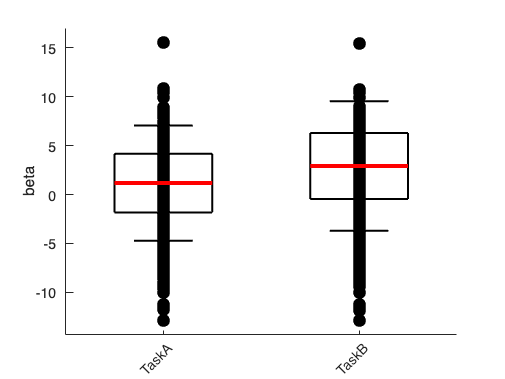

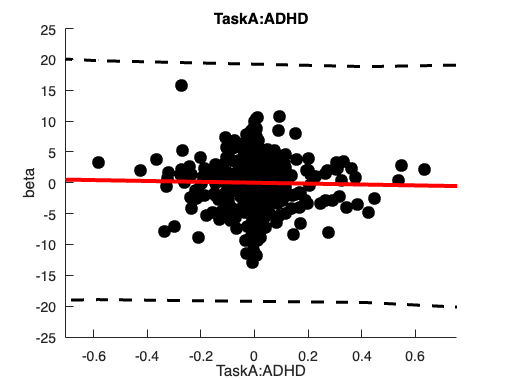

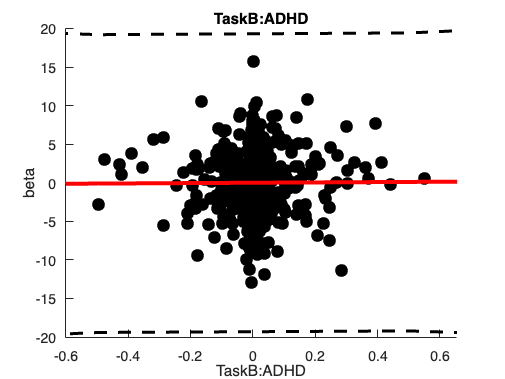

% In the table, you will see the group stats in 4 regions

%Let's say that you want to see the scatter plot from Region 3 for hbo
ROIGroupstats.scatterplot(5, 0.95, true) %Plot channel 1 (hbo): see Group1.probe.link

**Region of Interest (in hb data and stats)**

There are many ways to analyze in ROI:

- ROI in hb data: We can see the time series of that ROI results

- ROI after the first level

- ROI in the group level


%There are many option to do the ROI
% ROI in hb data: We can see the time series in that ROI
% ROI after the first level
% ROI in the group level (done)

% Let's see the ROI in the hb data
ROIhb = nirs.util.roiAverage(hb,Region,{'Region1','Region2','Region3','Region4'});
%Check this: 
ROIhb(1).probe.link

ans = 8×2 table
        ROI         type  
    ___________    _______

    {'Region1'}    {'hbo'}
    {'Region1'}    {'hbr'}
    {'Region2'}    {'hbo'}
    {'Region2'}    {'hbr'}
    {'Region3'}    {'hbo'}
    {'Region3'}    {'hbr'}
    {'Region4'}    {'hbo'}
    {'Region4'}    {'hbr'}


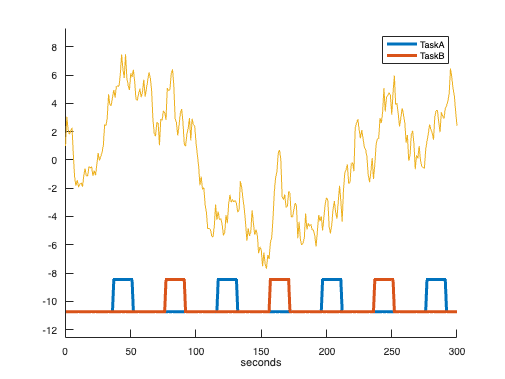

%You will see, this variable only has 10 data (5 regions X hb)
figure; ROIhb(10).draw(5) %hbo data from subject 10, region 3

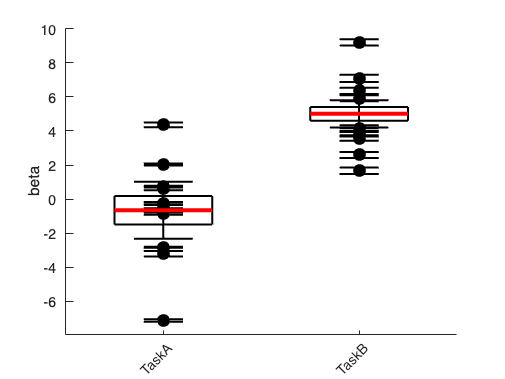

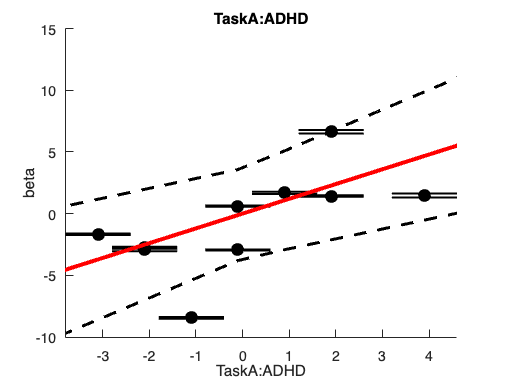

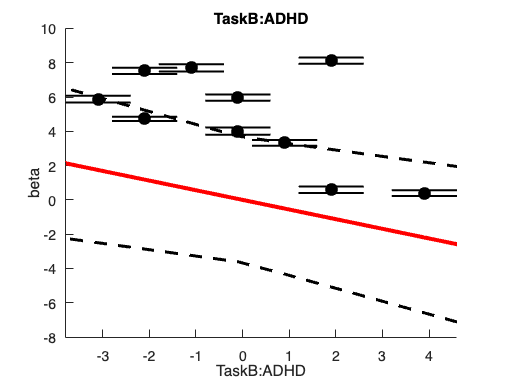


% Then, after this, you can run the first level, then the group level


% New function: ROI from tstat
roitbl=nirs.util.roi_from_tstat(GroupStats1,{'TaskA:ADHD','TaskB:ADHD'});
roitbl.weight(roitbl.weight<0)=0;
[~,roi]=nirs.util.roiAverage(Stats,roitbl);

job = nirs.modules.MixedEffects;
job.formula = 'beta ~ -1  + cond + cond:ADHD + (1|Subject)'; %continuous
job.robust = true;
job.include_diagnostics = true;
Group1roi = job.run(roi);  %only 1 roi average from that tstat

Group1roi.scatterplot(1, 0.95, true) %hbo data for TaskA:ADHD